**P.24**

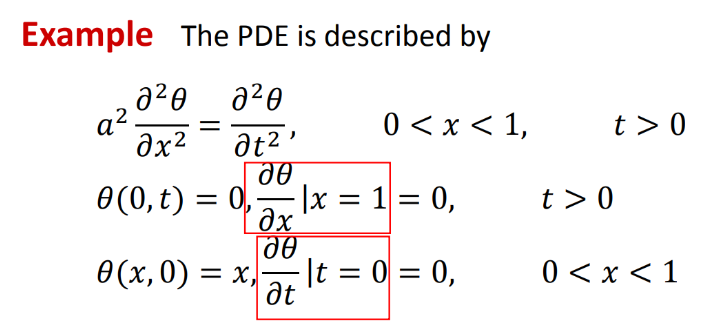

**Separation part**

clear
clc
syms x t u(x,t) L a
assume([L a],"positive")
WaveEq = a^2*diff(u,x,2) == diff(u,t,2)

$$WaveEq(x, t) = a^{2}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

Dx = diff(u,x);
BC0 = u(0,t) ==0;BCL = Dx(L,t) == 0;
t0 = u(x,0) == x

$$t0 = u\left(x,0\right)=x$$

Dt = diff(u,t);
Dt0 = Dt(x,0) == 0;
syms T(t) X(x)
SepVar = subs(WaveEq,u(x,t),X(x)*T(t));
BC0 = subs(BC0,u(0,t),X(0))

$$BC0 = X\left(0\right)=0$$

BCL = subs(BCL,u(L,t),X(L))

$$BCL = \frac{\partial }{\partial L}X\left(L\right)=0$$

T0 = subs(t0,u(x,0),T(0))

$$T0 = T\left(0\right)=x$$

DT = diff(T,t);
DT0 = subs(Dt0,Dt(x,0),DT(0))

$$DT0 = \left({\left(\frac{\partial }{\partial t}T\left(t\right)\right)|}_{t=0}\right)=0$$

SepVar = SepVar/(X(x)*T(t))

$$SepVar(x, t) = \frac{a^{2}\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=\frac{\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)}{T\left(t\right)}$$

syms lambda
assume(lambda,"positive")
assumeAlso(lambda > 0)
var = children(SepVar);
eqX = var(1) == -lambda^2

$$eqX = \frac{a^{2}\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

eqT = var(2) == -lambda^2

$$eqT = \frac{\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)}{T\left(t\right)}=-\lambda^{2}$$

X(x) = dsolve(eqX,BC0);
T(t) = dsolve(eqT,DT0)

$$T(t) = C_{1}\,\cos\left(\lambda \,t\right)$$

constantX = setdiff(symvar(X(x)),sym(['C',x,lambda,a]));
X(x) = subs(-X(x),constantX,sym('C2'))

$$X(x) = C_{2}\,\sin\left(\frac{\lambda \,x}{a}\right)$$

sln = subs(diff(X,x),x,L) == 0;
[lambda,parameter,cond] = solve(sln,lambda,"ReturnConditions",true);
n = sym("n",["integer", "positive"]);L = 1;
lambda = subs(lambda,[parameter,sym("L")],[n,L])

$$lambda = a\,\left(\frac{\pi }{2}+\pi \,n\right)$$

syms A ustruct(x,t);
sT(t) = subs(T(t),str2sym({'lambda','C1'}),{lambda,A});
sX(x) = subs(X(x),str2sym({'lambda','C2'}),{lambda,1});
ustruct(x,t) = sX(x)*sT(t)

$$ustruct(x, t) = A\,\sin\left(x\,\left(\frac{\pi }{2}+\pi \,n\right)\right)\,\cos\left(a\,t\,\left(\frac{\pi }{2}+\pi \,n\right)\right)$$

**Orthogonal Series Expansions**

syms Sigma
bnum(n) = simplify(int(x*subs(ustruct(x,0),A,1),x,[0 L]));
bden(n) = simplify(int(subs(ustruct(x,0),A,1)^2,x,[0 L]));
A = bnum/bden

$$A(n) = \frac{8\,{\left(-1\right)}^{n}}{\pi^{2}\,{\left(2\,n+1\right)}^{2}}$$

WaveStruct = subs(ustruct,sym("A"),A)

$$WaveStruct(x, t) = \frac{8\,{\left(-1\right)}^{n}\,\sin\left(x\,\left(\frac{\pi }{2}+\pi \,n\right)\right)\,\cos\left(a\,t\,\left(\frac{\pi }{2}+\pi \,n\right)\right)}{\pi^{2}\,{\left(2\,n+1\right)}^{2}}$$